% Live Script Durschnitt Geschwindkeit/Fluss Plots beider Ringstraßen
% Dazu Slider zu den jeweiligen Grünphasen

clc;
close;
clear;

dichte = 0:0.1:1;
laenge1 =3000;
laenge2 =3000;
iter = 2000;
v_max1 = 5;
v_max2 = 5;
p_troedel1 = 0.2;
p_troedel2 = 0.2;
ampel1 = 1500;
ampel2 = 1500;
t_gruen_Ampel1 = 65

t_gruen_Ampel1 = 65

t_gruen_Ampel2 =65

t_gruen_Ampel2 = 65

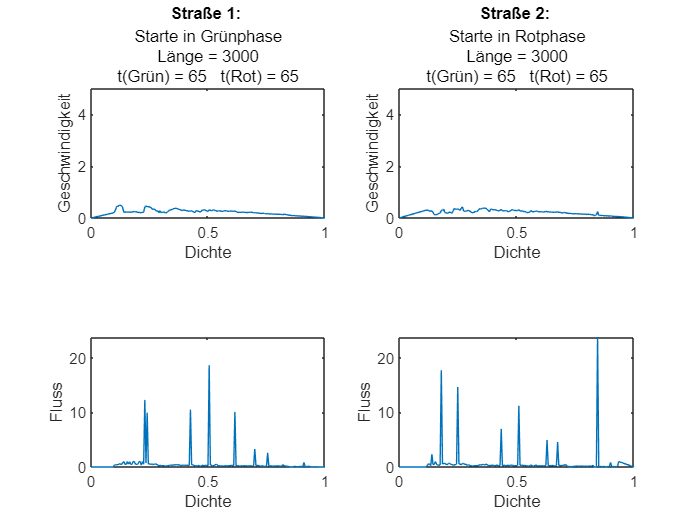

t_rot_Ampel1 = t_gruen_Ampel2;
t_rot_Ampel2 = t_gruen_Ampel1;

% Messintervall
%TODO: Messintervall?
x_min1=ampel1-100;
x_max1=ampel1+100;
x_min2=ampel2-100;
x_max2=ampel2+100;

% berechne Daten (Geschwindigkeit bzw. Fluss über Dichte in einem Messintervall) 
[B1] = berechneStrasse1(dichte, x_min1, x_max1, laenge1, iter, v_max1, p_troedel1, ampel1, t_gruen_Ampel1, t_rot_Ampel1);
[B2] = berechneStrasse2(dichte, x_min2, x_max2, laenge2, iter, v_max2, p_troedel2, ampel2, t_gruen_Ampel2, t_rot_Ampel2);

f_max = max(max(B1.mean_Var3), max(B2.mean_Var3));
v_max = max(v_max1, v_max2);

%und plotten
figure;
subplot(2,2,1);
plot(B1.Var1,B1.mean_Var2)
title('Straße 1: ')
subtitle({['Starte in Grünphase' ] 
    ['Länge = ' num2str(laenge1) ] 
    ['t(Grün) = ' num2str(t_gruen_Ampel1) '   t(Rot) = ' num2str(t_rot_Ampel1)  ]
    });
ylabel("Geschwindigkeit")
xlabel("Dichte")
ylim([0,v_max]);

subplot(2,2,3); 
plot(B1.Var1,B1.mean_Var3)
ylabel("Fluss")
xlabel("Dichte")
ylim([0,f_max])
 
subplot(2,2,2);
plot(B2.Var1,B2.mean_Var2)
title('Straße 2: ')
subtitle({['Starte in Rotphase' ] 
    ['Länge = ' num2str(laenge2) ] 
    ['t(Grün) = ' num2str(t_gruen_Ampel2) '   t(Rot) = ' num2str(t_rot_Ampel2)  ]
    });
ylabel("Geschwindigkeit")
xlabel("Dichte")
ylim([0,v_max]);

subplot(2,2,4); 
plot(B2.Var1,B2.mean_Var3)
ylabel("Fluss")
xlabel("Dichte")
ylim([0,f_max])

function [B] = berechneStrasse1(dichte, x_min, x_max, laenge, iter, v_max, p_troedel, ampel, t_gruen_Ampel1, t_rot_Ampel1)
r_lokal=[];
v_lokal=[];
f_lokal=[];

for r = dichte
    [ind1,val1] = Starte_gruene_Ampel_Nagel_Schreck(r, laenge, iter, v_max, p_troedel, ampel, t_gruen_Ampel1, t_rot_Ampel1);
    
    % Messintervall in Daten kennzeichnen
    intervall = ind1>=x_min & ind1<x_max;
    
    % lokale Dichte und Geschwindigkeiten filtern
    r_lokal = [r_lokal sum(intervall)/ (x_max-x_min)];
    v_lokal = [v_lokal sum(intervall .* val1) / (x_max-x_min)];
    
    % Fluss über x_min Grenze bestimmen
    f_lokal = [f_lokal sum(ind1>=x_min & circshift(ind1,1,2)<x_min)];
    
end

% Mittelwerte über lokale Dichten
A=table(r_lokal',v_lokal',f_lokal');
B=varfun(@mean,A,'GroupingVariables','Var1');

end %function

function [B] = berechneStrasse2(dichte, x_min, x_max, laenge, iter, v_max, p_troedel, ampel, t_gruen_Ampel2, t_rot_Ampel2)
r_lokal=[];
v_lokal=[];
f_lokal=[];

for r = dichte
    [ind2,val2] = Starte_rote_Ampel_Nagel_Schreck(r, laenge, iter, v_max, p_troedel, ampel, t_gruen_Ampel2, t_rot_Ampel2);
    
    % Messintervall in Daten kennzeichnen
    intervall = ind2>=x_min & ind2<x_max;
    
    % lokale Dichte und Geschwindigkeiten filtern
    r_lokal = [r_lokal sum(intervall)/ (x_max-x_min)];
    v_lokal = [v_lokal sum(intervall .* val2) / (x_max-x_min)];
    
    % Fluss über x_min Grenze bestimmen
    f_lokal = [f_lokal sum(ind2>=x_min & circshift(ind2,1,2)<x_min)];
    
end

% Mittelwerte über lokale Dichten
A=table(r_lokal',v_lokal',f_lokal');
B=varfun(@mean,A,'GroupingVariables','Var1');
end %function